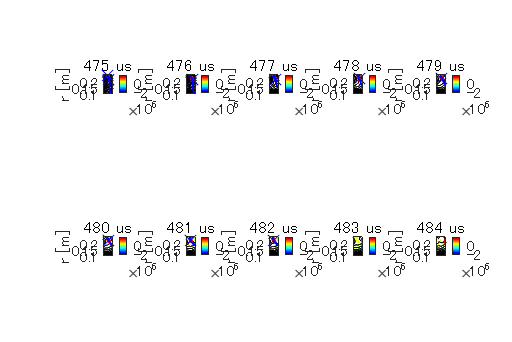

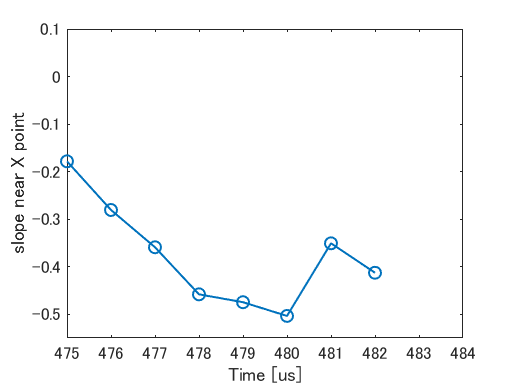

max_slope = 0.5036

min_slope = -0.5036

clearvars 
%電流シートの傾きを求める（test）
%磁気面上での表示、時系列での傾き
%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save='C:\Users\kuru1\OneDrive - g.ecc.u-tokyo.ac.jp\過去データ解析\220705\slope';

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得
%  node='Crowbar_us_';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
%  pat=454;   % 検索パターン（数値なら一致検索、文字なら含む検索）　
% 
% subT=searchlog(T,node,pat);% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成

% IDXlist=[2897 2906 2907 2912 2913];
% tcal=repmat([471 480],numel(IDXlist),1);

% IDXlist=[2920 2888 2879 2900];
% tcal=[474 483; 468 477; 468 477; 471 480];

IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
% %(a)211223/IDX2870:2920(42:44)/2911:2913/dtacq3592:3594
% %(b)211224/IDX2922:2950(4,5,8)/2925,2926,2927/dtacq3606,3607,3609
% %(c)211224/IDX2922:2950(10,12)/2931,2933/dtacq3611,3613
% %(d)211224/IDX2922:2950(26:29)/2947:2950/dtacq3626-3629
% %(e)211224/IDX2922:2950(21,22,25)/2942,2943,2946/dtacq3621,3622,3625
% 
%tcal=[472 472 472 475 475 475 481 481 475 475 475 475 482 482 482];

% wide=zeros(numel(IDXlist),numel(tcal)); %電流シートの半値幅
% xr=zeros(numel(IDXlist),numel(tcal));
% Vzl=zeros(numel(IDXlist),numel(tcal));
% Vzr=zeros(numel(IDXlist),numel(tcal));

for i=1%numel(IDXlist)
    IDX=IDXlist(i);
    tstart=475;%(i,1)
    tend=484;
%     tend=tcal(i,2);
    cal_diff(T, IDX, pathname, tstart, tend);
%     [wide(i),xr(i),Vzl(i),Vzr(i)]=jtsheetcalc(T, IDX, pathname, tstart, tend);
%     [wide(i,:),xr(i,:),Vzl(i,:),Vzr(i,:)]=cal_vz(T, IDX, pathname, tstart, tend);
end

function [date, shot, TF_shot, offset_TF, i_EF, start, v_TF, d_tacq, d_tacqTF, n] = getinput(T,IDX)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
offset_TF=isfinite(TF_shot);

if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end

start=T.Period_StartTime_(IDX);
v_TF=T.TF_kV_(IDX); %TF[kV]

d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);

n=50; %rz方向のメッシュ数
end

function cal_diff(T, IDX, pathname, tstart, tend)
trange = tstart:tend+1;
tsize = tend-tstart+1;

row = 2;
column =ceil(tsize/row);

[date, ~, ~, ~, i_EF, ~, ~, d_tacq, d_tacqTF, n] = getinput(T,IDX);%Tのテーブルから入力のリストを出力
[grid2D, data2D] = pcbdata(date, d_tacq, d_tacqTF, trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
% [xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

% %midの傾きを求める
% for i=1:tsize
%     dmid=gradient(grid2D.zq(1,squeeze(mid(2:end,:,i))));
%     figure
%     plot(grid2D.rq(2:end,1),dmid)
% end

%X点での勾配
p=zeros(2,tsize);
figure('Position',[0,0,600,400])
for i=1:tsize
%     r_xind=ceil(n/2);
%     z_xind=ceil(n/2);
    if sum(xpoint(:,:,i))>0   
        r_xind=r_index(xpoint(:,:,i));
        z_xind=mid(xpoint(:,:,i),:,i);
        if numel(r_xind)>1
            [~,I]=min(psimid(r_xind));
            r_xind=r_xind(I);
            z_xind=z_xind(I);
        end
        
        r_s=max(2,r_xind-5);
        r_n=min(n,r_xind+5);
        p(:,i)=polyfit(grid2D.rq(r_s:r_n,1),grid2D.zq(1,squeeze(mid(r_s:r_n,:,i))),1);
        diff=polyval(p(:,i),grid2D.rq(r_s:r_n,1));
        subplot(row,column,i)
        %contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),13,'LineStyle','none');
        contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),8,'w-','LineWidth',0.2);
        colormap(jet)
        caxis([-2.5*1e+6,1.6*1e+6])
%         caxis([-1.5*1e+6,1*1e+6])
        %colormap(jet)
        axis image
        axis tight manual
        hold on
        contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),20,'black','LineWidth',0.3)
        colorbar('Location','eastoutside')
        plot(diff,grid2D.rq(r_s:r_n,1),'r-','LineWidth',2)
        plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"bx",'MarkerSize',8)
        plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1),'b-','LineWidth',1)
        hold off
        alpha(0.3)
        ylim([0.1 grid2D.rq(end,1)])
        xlim([-0.04 0.04])
        xlabel('z [m]')
        ylabel('r [m]')
        title(string(tstart+i-1)+' us')

        if z_xind==1 || z_xind==n
            p(:,i)=NaN;
        end
    else
        p(:,i)=NaN;
    end   
end
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'slopefig.png'))
% close

% sgtitle(strcat('IDX=',num2str(IDX)))

figure
plot(tstart:tend,p(1,:),'o-','LineWidth',1)
xlim([tstart tend])
ylim([-0.55 0.1])
xlabel('Time [us]')
ylabel('slope near X point')
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'slope.png'))

max_slope=max(abs(p(1,:)))
min_slope=min(p(1,:))

% %速度Vの各成分を計算
% Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2),tsize);
% % Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2),tsize);
% for i=1:tsize
%     Vz(:,:,i)=data2D.Et(:,:,i)./data2D.Br(:,:,i);
% %     Vr(:,:,i)=-data2D.Et(:,:,i)./data2D.Bz(:,:,i);
%     vzind=isoutlier(Vz(:,:,i),'median',1);
%     Vz(vzind)=NaN;
% %     vrind=isoutlier(Vr(:,:,i),'median',1);
% %     Vr(vrind)=NaN;
%     clear vzind vrind
%     Vz(abs(Vz) > 10*1e+4) = NaN;
% %     Vr(abs(Vr) > 10*1e+4) = NaN;
% end
% 
% 
% %X点を通るBrのz方向分布から電流シート端を定義
% figure
% 
% Vz_edge1=zeros(tsize,1);
% Vz_edge2=zeros(tsize,1);
% Vz_left=zeros(tsize,1);
% Vz_right=zeros(tsize,1);
% sheetl=zeros(tsize,1);
% sheetr=zeros(tsize,1);
% for i=1:tsize
%     r_xind=25;
%     z_xind=24;
%     if sum(xpoint(:,:,i))>0   
%         r_xind=r_index(xpoint(:,:,i));
%         z_xp=grid2D.zq(1,mid(xpoint(:,:,i),:,i));
%         z_xind=mid(xpoint(:,:,i),:,i);
%         if numel(r_xind)>1
%             [~,I]=min(psimid(r_xind));
%             r_xind=r_xind(I);
%             z_xind=z_xind(I);
%             z_xp=z_xp(I);
%         end
%     else
%         z_xp=-1; %グラフに表示させない
%     end
%     [edge1,~]=islocalmax(data2D.Br(r_xind,:,i));
%     [edge2,~]=islocalmin(data2D.Br(r_xind,:,i));
%     %maxのBrの半値幅を求める（以下の方法は記述は端的だが場合分けが必要なので大変）
% %     eps=4e-2*data2D.Br(r_xind,edge1,i);
% %     lind=find(abs(data2D.Br(r_xind,:,i)-0.5*data2D.Br(r_xind,edge1,i))<eps)
% %     rind=find(abs(data2D.Br(r_xind,:,i)-0.5*data2D.Br(r_xind,edge2,i))<eps)
%     Vz_edge1(i)=Vz(r_xind,edge1,i);
%     Vz_edge2(i)=Vz(r_xind,edge2,i);
%     %maxのBrのa倍の幅を求める
%     lind=0;
%     rind=0;
%     a=0.5;
%     for j=r_index(edge1):z_xind
%         if (data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge1,i))*(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge1,i))<=0
%             if abs(data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge1,i))<abs(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge1,i))
%                 lind=j;
%                 sheet_left=grid2D.zq(1,j);
%             else
%                 lind=j+1;
%                 sheet_left=grid2D.zq(1,j+1);
%             end  
%         end
%     end
%     for j=z_xind:r_index(edge2)
%         if (data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge2,i))*(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge2,i))<=0
%             if abs(data2D.Br(r_xind,j,i)-a.*data2D.Br(r_xind,edge2,i))<abs(data2D.Br(r_xind,j+1,i)-a.*data2D.Br(r_xind,edge2,i))
%                 rind=j;
%                 sheet_right=grid2D.zq(1,j);
%             else
%                 rind=j+1;
%                 sheet_right=grid2D.zq(1,j+1);
%             end
%         end
%     end
%     Vz_left(i)=Vz(r_xind,lind,i);
%     Vz_right(i)=Vz(r_xind,rind,i);
%     sheetl(i)=lind;
%     sheetr(i)=rind;
%     
% %Brの分布を各時刻でplot
% subplot(column,row,i)
% plot(grid2D.zq(1,:),data2D.Br(r_xind,:,i),'k-')
% xline(z_xp,'b-')
% xline(grid2D.zq(1,edge1),'r--')
% xline(grid2D.zq(1,edge2),'r--')
% xline(grid2D.zq(1,lind),'r-')
% xline(grid2D.zq(1,rind),'r-')
% yline(0,'k-.')
% xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
% xlabel('z [m]')
% ylabel('Br')
% title(string(trange(i))+' us')
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% %両端でのVzの大きさ
% figure
% plot(tstart:tend,Vz_edge1)
% hold on
% plot(tstart:tend,-1.*Vz_edge2)
% plot(tstart:tend,Vz_left)
% plot(tstart:tend,-1.*Vz_right)
% hold off
% legend('Vz at left edge','Vz at right edge','Vz at left sheet','Vz at right sheet')
% xlabel('Time [us]')
% ylabel('|Vz| [m/s]')
% 
% %磁気面のplot
% figure('Position', [0 0 1500 1500],'visible','on');
% start=0; %460+?
% %  t_start=470+start;
%  for m=1:10 %図示する時間
%      i=start+m; %end
%      t=trange(i);
%      subplot(2,5,m)
%     contourf(grid2D.zq(1,:),grid2D.rq(:,1),-1.*data2D.Jt(:,:,i),10,'LineStyle','none')
%     colormap(jet)
%     axis image
%     axis tight manual
%     %     xlim([-0.02 0.02])
%     %     ylim([0.12 0.27])
%     caxis([-2.5*1e+6,2.5*1e+6]) %カラーバーの軸の範囲
%     %caxis([-1*1e+6,1*1e+6])
%     %caxis([-maxrange,maxrange])
%     colorbar('Location','eastoutside')
%     %zlim([-1 1])
%     %colormap(bone)
%     %カラーバーのラベル付け
% %     c = colorbar;
% %     c.Label.String = 'Jt [A/m^{2}]';
%     hold on
%     plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1))
%     contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),50,'black')
%     plot(grid2D.zq(1,squeeze(mid(opoint(:,:,i),:,i))),grid2D.rq(opoint(:,:,i),1),"bo")
%     plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"bx")
%     xline(grid2D.zq(1,sheetl(i)),'b-','LineWidth',1)
%     xline(grid2D.zq(1,sheetr(i)),'b-','LineWidth',1)
%     hold off
%     title(string(t)+' us')
%     xlabel('z [m]')
%     %ylabel('r [m]')
% %     ylim([0.1 grid2D.rq(end,1)])
% %     xlim([-0.04 0.04])
% %     ax = gca; %y軸を消す
% %     ax.YTickLabel = cell(size(ax.YTickLabel)); 
%  end
%  
%  sgtitle(strcat('IDX=',num2str(IDX)))


% %mid線に沿ったプロット
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.Jt(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Jt')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.Bz(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Bz')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),diag(data2D.psi(:,mid(:,1,i),i)),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('psi')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),data2D.Br(:,sheetl(i),i),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Br')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% figure
% for i=1:tsize
%    subplot(column,row,i)
%    plot(grid2D.rq(:,1),data2D.Br(:,sheetr(i),i),'k-')
%    yline(0,'k-.')
%    xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
%    xlabel('r [m]')
%    ylabel('Br')
%    title(string(trange(i))+' us') 
% end
% sgtitle(strcat('IDX=',num2str(IDX)))

%figure
%     subplot(row,column,i);
%     contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vz(:,:,i),20,'LineStyle','none')
%     colormap(jet)
%     axis image
%     axis tight manual
%     caxis([-5*1e+4,5*1e+4])
%     colorbar('Location','eastoutside')
%     hold on
%     plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1))
%     contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),50,'black')
%     plot(grid2D.zq(1,squeeze(mid(opoint(:,:,i),:,i))),grid2D.rq(opoint(:,:,i),1),"ro")
%     plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"rx")
%     hold off
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('r [m]')    
% end
% sgtitle(strcat('IDX',num2str(IDX),': Vz [m/s]'))
% 
% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vzplot_2.png'))
% close


% % figure
% %figure('Position', [0 0 1500 1500],'visible','on');
% 
% %%%z方向視線からのJt
% Jt_fromz=zeros(tsize,n);
% xJt=zeros(tsize,1);
% for i=1:tsize
%     if sum(maxxp(:,i))>0
%         r_maxxp=r_index(maxxp(:,i));
%         r_s=max(1,r_maxxp-15);
%         r_n=min(n,r_maxxp+15);
%         for j=1:n
%             Jt_fromz(i,j)=sum(data2D.Jt(r_s:r_n,j,i))/(r_n-r_s+1);            
%         end
%     end
% %   各時刻でのz方向視線からのJtのプロット
%     subplot(row,column,i);
%     plot(grid2D.zq(1,:),Jt_fromz(i,:))
%     yline(0,'b-')
%     xline(grid2D.zq(1,squeeze(mid(maxxp(:,i),:,i))),'r-')
%     ylim([-3e+6 3e+6])
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('Jt from z [A/m^{2}]')
%     
%     xJt(i,1)=Jt_fromz(i,squeeze(mid(maxxp(:,i),:,i)));
% end
% 
% %X点でのJtが最小の時刻
% [xJt_min,tmin]=min(xJt);
% 
% %半値の交点がぴったり2点の場合に半値幅を求める（交点が2個以外を考慮したverも作りたい）
% lind=0;
% rind=0;
% for j=1:squeeze(mid(maxxp(:,tmin)))
%     if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
%         if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
%             lind=j;
%             sheet_left=grid2D.zq(1,j);
%         else
%             lind=j+1;
%             sheet_left=grid2D.zq(1,j+1);
%         end  
%     end
% end
% 
% for j=squeeze(mid(maxxp(:,tmin))):n-1
%     if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
%         if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
%             rind=j;
%             sheet_right=grid2D.zq(1,j);
%         else
%             rind=j+1;
%             sheet_right=grid2D.zq(1,j+1);
%         end  
%     end
% end
% 
% %[[output]]
% wide=sheet_right-sheet_left;
% xr=grid2D.rq(maxxp(:,tmin),1);
% %x_z=grid2D.zq(1,squeeze(mid(maxxp(:,tmin)
% 
% %X点でのJtのプロット
% % figure
% % plot(tstart:tend, xJt)
% % xlabel('Time [us]')
% % ylabel('Jt at Xpoint[A/m^{2}]')
% 
% %電流シート高さLの定義
% Jt_fromr=zeros(n,1);
% for j=1:n
%     Jt_fromr(j,1)=sum(data2D.Jt(j,lind:rind))/(rind-lind+1);            
% end
% %xJt_r=Jt_fromr(r_maxxp,1);
% 
% %速度Vの各成分を計算
% % Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% % Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% Vz(:,:)=data2D.Et(:,:,tmin)./data2D.Br(:,:,tmin);
% Vr(:,:)=-data2D.Et(:,:,tmin)./data2D.Bz(:,:,tmin);
% %vが大きすぎるところを外れ値検索で外す
% vzind=isoutlier(Vz,'median',1);
% Vz(vzind)=NaN;
% vrind=isoutlier(Vr,'median',1);
% Vr(vrind)=NaN;
% clear vzind vrind
% Vz(abs(Vz) > 10*1e+4) = NaN;
% Vr(abs(Vr) > 10*1e+4) = NaN;
% 
% %%%z方向視線からのVz
% %NaNが含まれる場合は対応していない
% L_s=max(1,r_maxxp-5);
% L_n=min(n,r_maxxp+5);
% %[[output]]
% Vzl=sum(Vz(L_s:L_n,lind-5:lind-1),'all')/(5*(L_n-L_s+1));
% Vzr=sum(Vz(L_s:L_n,rind+1:rind+5),'all')/(5*(L_n-L_s+1));
% %Vz(L_s:L_n,rind+1:rind+5)
% 
% 
% %plot
% 
% % %X点でのJtが最小の時刻でのz方向視線からのJtのプロット
% % figure('Position', [0 0 1000 500],'visible','on');
% figure
% subplot(1,2,1)
% plot(grid2D.zq(1,:),Jt_fromz(tmin,:))
% xlim([grid2D.zq(1,1) grid2D.zq(1,n)])
% yline(0,'k-')
% yline(xJt_min*0.5,'b--') %半値幅
% xline(grid2D.zq(1,squeeze(mid(maxxp(:,tmin),:,tmin))),'r-')
% xline(sheet_left,'b-')
% xline(sheet_right,'b-')
% title(string(trange(tmin))+' us')
% xlabel('z [m]')
% ylabel('Jt from z [A/m^{2}]')
% 
% %tminでのr方向視線からのJtのプロット
% %figure
% subplot(1,2,2)
% plot(grid2D.rq(:,1),Jt_fromr)
% xlim([grid2D.rq(1,1) grid2D.rq(n,1)])
% yline(0,'k-')
% xline(xr,'r-')
% % yline(xJt_r*0.5,'b--') %r方向視線での半値幅
% yline(xJt_min*0.5,'b--') %z方向視線での半値幅
% title(string(trange(tmin))+' us')
% xlabel('r [m]')
% ylabel('Jt from r [A/m^{2}]')
% 
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% % saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'Jtplot.png'))
% % close
%    
% %磁気面のプロット
% %figure('Position', [0 0 1000 500],'visible','on');
% figure
% %f=figure;
% %f.WindowState = 'maximized';
% subplot(1,3,1)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),data2D.Jt(:,:,tmin),10,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-2.7*1e+6,3*1e+6]) %カラーバーの軸の範囲
% %caxis([-maxrange,maxrange])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Psi')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% subplot(1,3,2)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vz(:,:),20,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-5*1e+4,5*1e+4])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Vz [m/s]')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% subplot(1,3,3)
% contourf(grid2D.zq(1,:),grid2D.rq(:,1),Vr(:,:),20,'LineStyle','none')
% colormap(jet)
% axis image
% axis tight manual
% caxis([-5*1e+4,5*1e+4])
% colorbar('Location','eastoutside')
% hold on
% plot(grid2D.zq(1,squeeze(mid(:,:,tmin))),grid2D.rq(:,1))
% contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,tmin)),35,'black')
% plot(grid2D.zq(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),grid2D.rq(opoint(:,:,tmin),1),"ro")
% plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),grid2D.rq(xpoint(:,:,tmin),1),"rx")
% xline(sheet_left,'r-','LineWidth',1)
% xline(sheet_right,'r-','LineWidth',1)
% hold off
% title('Vr [m/s]')
% xlabel('z [m]')
% ylabel('r [m]')
% 
% sgtitle(strcat('IDX=',num2str(IDX)))
% 
% % saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vplot.png'))
% % close

end
